## H operator

G_xy = zeros(2,3,6);

G_xy(:,:,1) = G_10(idx,:);
G_xy(:,:,2) = G_20(idx,:);
G_xy(:,:,3) = G_30(idx,:);
G_xy(:,:,4) = G_40(idx,:);
G_xy(:,:,5) = G_50(idx,:);
G_xy(:,:,6) = G_60(idx,:);

H = zeros(2,2,6);
norm_H_I= zeros(6,1);

for k = 1:6
    Gk = G_xy(:,:,k);
    H(:,:,k) = Gk*((Gk.'*Gk)\Gk.'); % G*[(G'*G)^-1]*G'
    norm_H_I(k) = norm(H(:,:,k)-eye(2));
end

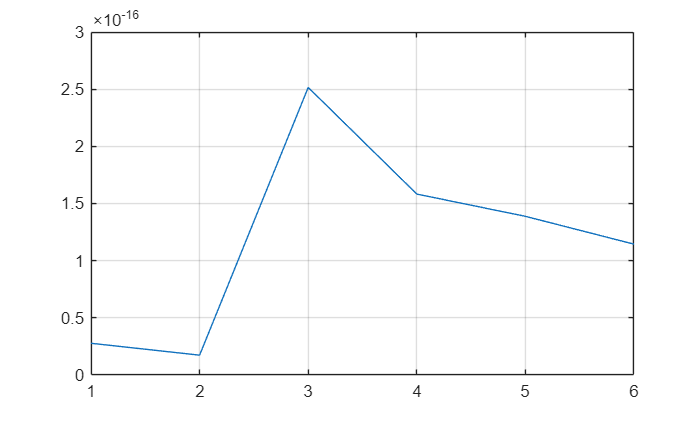

figure;
plot(norm_H_I);  grid on;

### Impulsion at t = 10 s (with lsqr)

[t_10_lsqr, X_10_lsqr, te_10_lsqr, Xe_10_lsqr] = ode45(@(t,x) proj_dynamics(t,x, D, S, M, Il, It, ...
                                   rho0, g0, a0, Rearth, Mach_table, CD_table, CL_table, ...
                                   Cmagf_table, Cmagm_table, CMq_table, CMa_table, ...
                                   Cspin_table, interpCoeff), [10 200], state0_10,options);

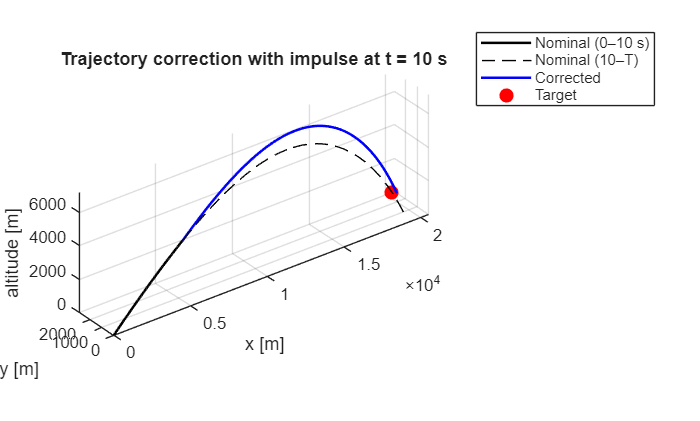

%% --- Nominal trajectory ---

figure; 

plot3(X_nom_plot(:,1), ...
      X_nom_plot(:,2), ...
     -X_nom_plot(:,3), 'k', 'LineWidth',1.5); 
hold on

plot3(X_nom_post(:,1), ...
      X_nom_post(:,2), ...
     -X_nom_post(:,3), 'k--');

%% --- Perturbed trajectory ---

plot3(X_10_lsqr(:,1), X_10_lsqr(:,2), -X_10_lsqr(:,3),'b', 'LineWidth',1.5);

% --- Target ---

plot3(X_cible(1),X_cible(2),-X_cible(3),'ro','MarkerSize',8,'MarkerFaceColor','r');

grid on; axis equal
xlabel('x [m]'); ylabel('y [m]'); zlabel('altitude [m]');
legend('Nominal (0–10 s)', 'Nominal (10–T)', ...
       'Corrected', 'Target');
title('Trajectory correction with impulse at t = 10 s');

### Impulsion at t = 10 s (without lsqr)

c_10_new = (((G_10(idx,:).'*G_10(idx,:))\G_10(idx,:).'))*delta_cible(idx) % delta_cible = G*c

c_10_new =    -5.7828
   41.4696
 -470.0000


delta_x10_new = zeros(n,1);
delta_x10_new(4:6) = c_10_new;

state0_10_new = x_10 + delta_x10_new;

[t_10_wlsqr, X_10_wlsqr, te_10_wlsqr, Xe_10_wlsqr] = ode45(@(t,x) proj_dynamics(t,x, D, S, M, Il, It, ...
                                   rho0, g0, a0, Rearth, Mach_table, CD_table, CL_table, ...
                                   Cmagf_table, Cmagm_table, CMq_table, CMa_table, ...
                                   Cspin_table, interpCoeff), [10 200], state0_10_new,options);

error_10_new = X_cible-Xe_10_wlsqr'

error_10_new = 1.0e+04 *

   -1.0824
   -0.0559
   -0.0000
    0.0031
   -0.0005
   -0.0095
   -0.0001
    0.0000
    0.0001
   -0.0000
    0.0119
    0.0010
   -0.0007


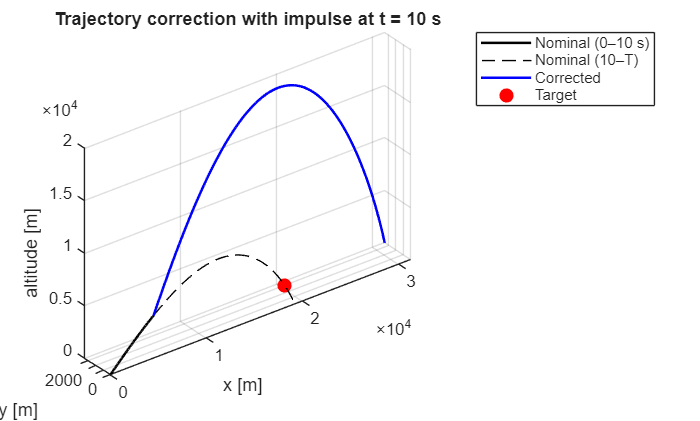

%% --- Nominal trajectory ---

figure; 

plot3(X_nom_plot(:,1), ...
      X_nom_plot(:,2), ...
     -X_nom_plot(:,3), 'k', 'LineWidth',1.5); 
hold on

plot3(X_nom_post(:,1), ...
      X_nom_post(:,2), ...
     -X_nom_post(:,3), 'k--');

%% --- Perturbed trajectory ---

plot3(X_10_wlsqr(:,1), X_10_wlsqr(:,2), -X_10_wlsqr(:,3),'b', 'LineWidth',1.5);

% --- Target ---

plot3(X_cible(1),X_cible(2),-X_cible(3),'ro','MarkerSize',8,'MarkerFaceColor','r');

grid on; axis equal
xlabel('x [m]'); ylabel('y [m]'); zlabel('altitude [m]');
legend('Nominal (0–10 s)', 'Nominal (10–T)', ...
       'Corrected', 'Target');
title('Trajectory correction with impulse at t = 10 s');

### Impulsion at t = 10 s (with eye correction)

c_10_new_2 = inv(G_10(idx,:)'*G_10(idx,:)+eye(3))*G_10(idx,:)'*delta_cible(idx) % delta_cible = G*c

c_10_new_2 =    45.7368
   60.3722
   -7.5757


delta_x10_new_2 = zeros(n,1);
delta_x10_new_2(4:6) = c_10_new_2;

state0_10_new_2 = x_10 + delta_x10_new_2;

[t_10_we, X_10_we, te_10_we, Xe_10_we] = ode45(@(t,x) proj_dynamics(t,x, D, S, M, Il, It, ...
                                   rho0, g0, a0, Rearth, Mach_table, CD_table, CL_table, ...
                                   Cmagf_table, Cmagm_table, CMq_table, CMa_table, ...
                                   Cspin_table, interpCoeff), [10 200], state0_10_new_2,options);

error_10_new_2 = X_cible-Xe_10_we'

error_10_new_2 =  -147.0957
  223.9084
   -0.0000
   -0.7054
  -18.8350
    1.0868
   -0.1822
   -0.4728
    0.8460
   -0.6460
   22.8421
    7.3537
  -15.6845


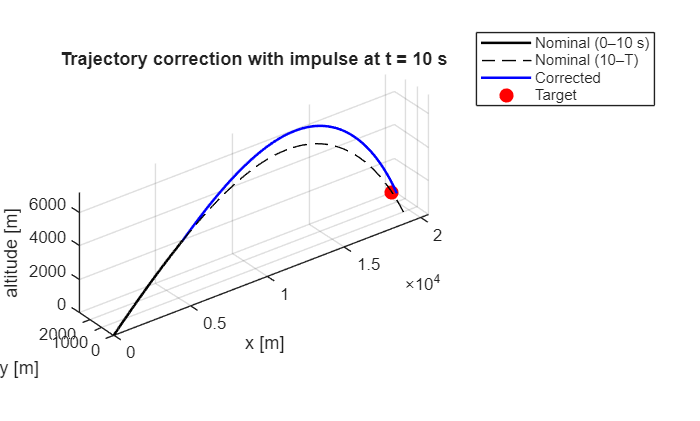

%% --- Nominal trajectory ---

figure; 

plot3(X_nom_plot(:,1), ...
      X_nom_plot(:,2), ...
     -X_nom_plot(:,3), 'k', 'LineWidth',1.5); 
hold on

plot3(X_nom_post(:,1), ...
      X_nom_post(:,2), ...
     -X_nom_post(:,3), 'k--');

%% --- Perturbed trajectory ---

plot3(X_10_we(:,1), X_10_we(:,2), -X_10_we(:,3),'b', 'LineWidth',1.5);

% --- Target ---

plot3(X_cible(1),X_cible(2),-X_cible(3),'ro','MarkerSize',8,'MarkerFaceColor','r');

grid on; axis equal
xlabel('x [m]'); ylabel('y [m]'); zlabel('altitude [m]');
legend('Nominal (0–10 s)', 'Nominal (10–T)', ...
       'Corrected', 'Target');
title('Trajectory correction with impulse at t = 10 s');